# Práctica 2. Filtros FIR y IIR

## 2.1 Cálculo de la salida de un filtro FIR con Matlab en el dominio del tiempo

Se define un filtro FIR a partir de la siguiente ecuación en diferencias:


$$y\left\lbrack n\right\rbrack =\frac{1}{2}x\left\lbrack n\right\rbrack +\frac{1}{3}x\left\lbrack n-1\right\rbrack +\frac{1}{4}x\left\lbrack n-2\right\rbrack$$


Sea $x\left\lbrack n\right\rbrack =2^n$para $0\le n\le 3$($x\left\lbrack n\right\rbrack =0$ en otro caso)

### Para el uso de fracciones introducir formar rat

format rat

### a) Emplea 'conv(x,h)' para obtener la señal de salida del filtro y representalo con 'stem(y)'

En **Papel**:


$$x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack +2\delta \left\lbrack n-1\right\rbrack +4\delta \left\lbrack n-2\right\rbrack +8\delta \left\lbrack n-3\right\rbrack$$


En **Matlab:**


$$x=\left\lbrack 1\;2\;3\;4\right\rbrack$$


#### Código:

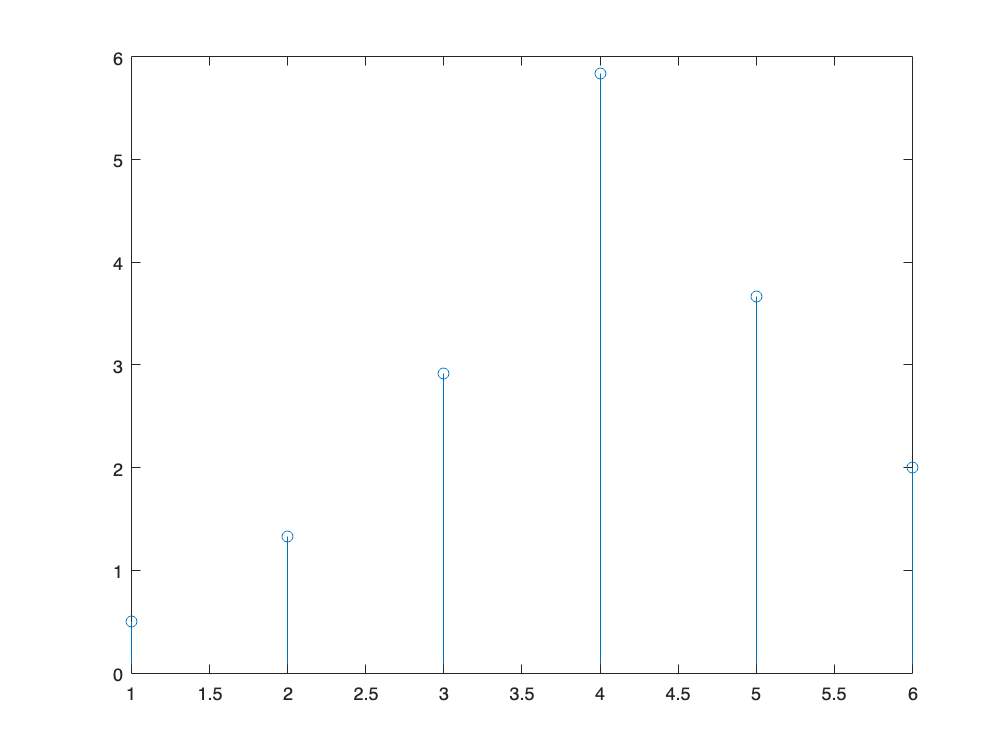

% x[n] = 2^n para (0 <= n <= 3) 
% h[n] = 1/2d[n] + 1/3d[n-1] + 1/4d[n-2]
%   d=delta
x = [1 2 4 8];
h = [1/2 1/3 1/4];

y = conv(x,h);
stem(y)

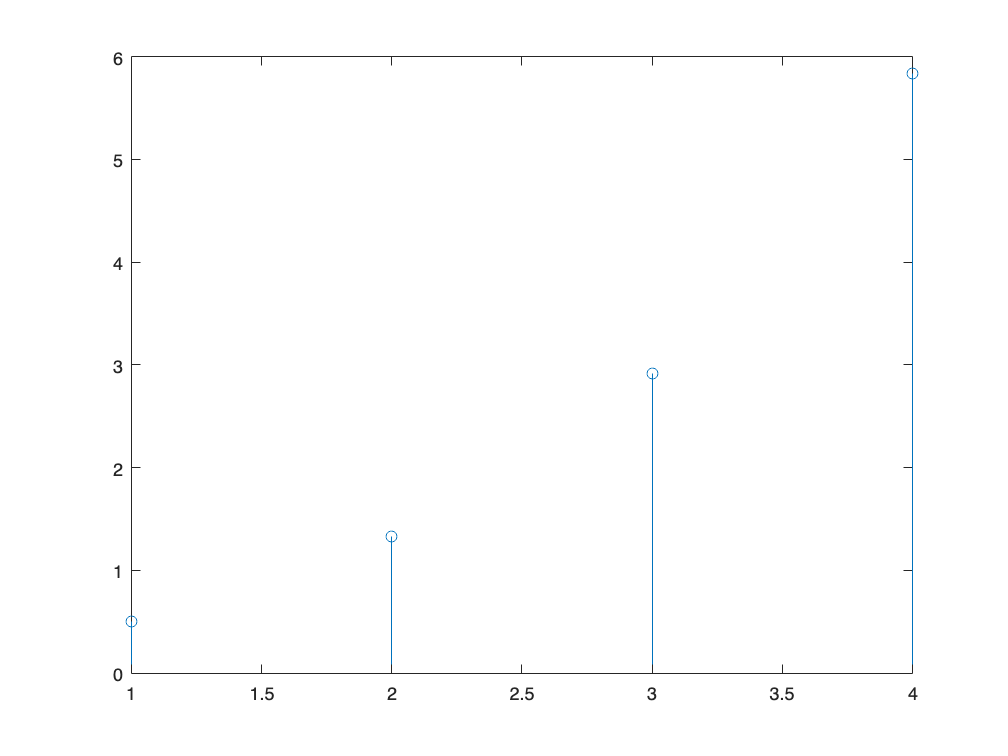

% Otra forma:
n=0:3;
x=2.^n;
h=[1/2 1/3 1/4];
y=filter(h,1,x);
stem(y)

### b) Define un vector de índices n y ejecuta stem(n,y) para que la representación en Matlab coincida con la señal de salida y[n] que se represento sobre el papel al hacer el PreLab

#### Código:

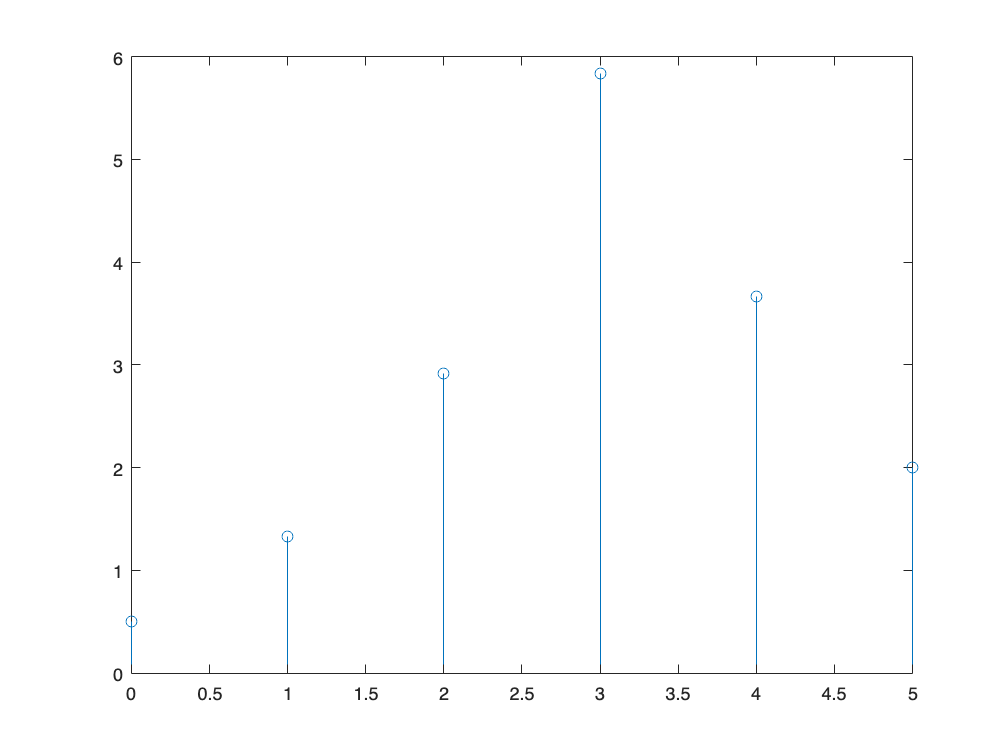

y = conv([1 2 4 8],[1/2 1/3 1/4]);
n = 0:5;

stem(n, y)

### d) Utiliza el comando 'filter(b,a,x)' para obtener la salida del sistema en el ejemplo anterior y compara el resultado con el obtenido mediante 'conv(x,h)'


$$y=\textrm{filter}\left(b,a,x\right)$$


- **y: ***señal de salida*

- **b:*** vector con los coeficientes del filtro FIR*

- **a:** *debe valer 1 para un filtro FIR.*

- **x:** *señal de entrada.*

#### Código:

b = h;
a = 1;  % Por ser un filtro FIR
y = filter(b, a, x)

y =        1/2            4/3           35/12          35/6     


stem(y)

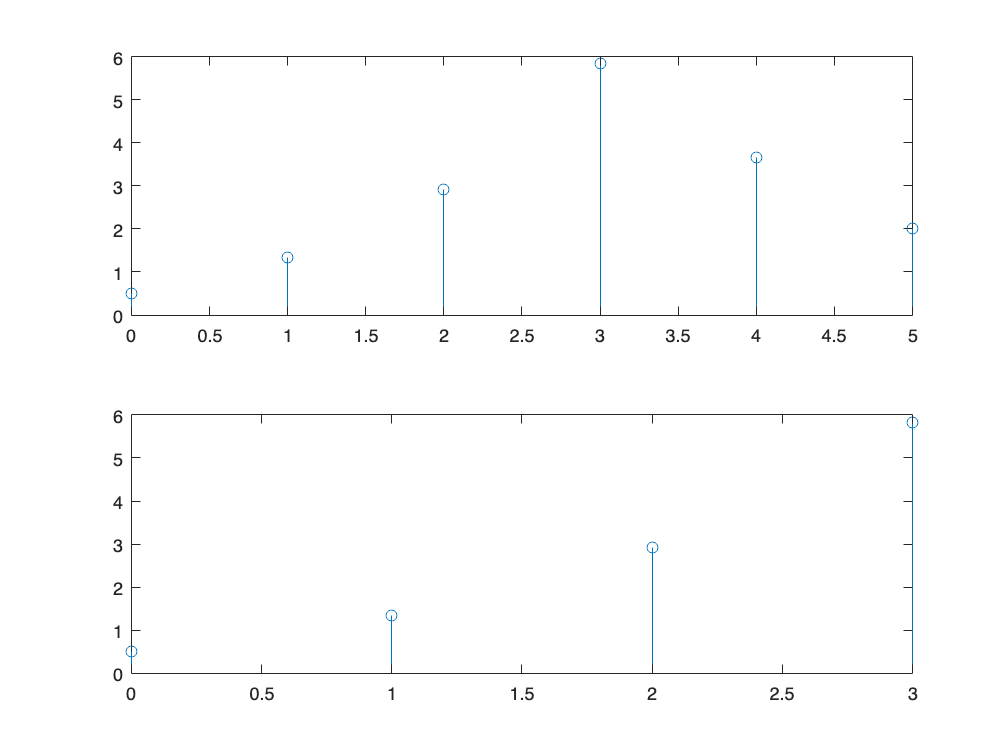

n1 = 0:5;
n2 = 0:3;
subplot(211), stem(n1,conv(x,h))
subplot(212), stem(n2,filter(b,a,x))

#### Solución:

Filter te devuelve la salida hasta con la longitud de la entrada, es decir, como la entrada es 0:3, la salida también será 0:3.

## 2.2 Representación de la respuesta en frecuencia de un filtro FIR


$$y\left\lbrack n\right\rbrack =\sum_{k=0}^M b_k x\left\lbrack n-k\right\rbrack \to y\left\lbrack n\right\rbrack =H\left(e^{j\overset{\wedge }{w} } \right)$$
 

### a) Emplea 'freqz(b,a,w)' para obtener la respuesta en frecuencia del filtro. Concretamente un vector de 121 valores de frecuencia que abarquen desde -$\pi$a$\pi$.

#### Código:

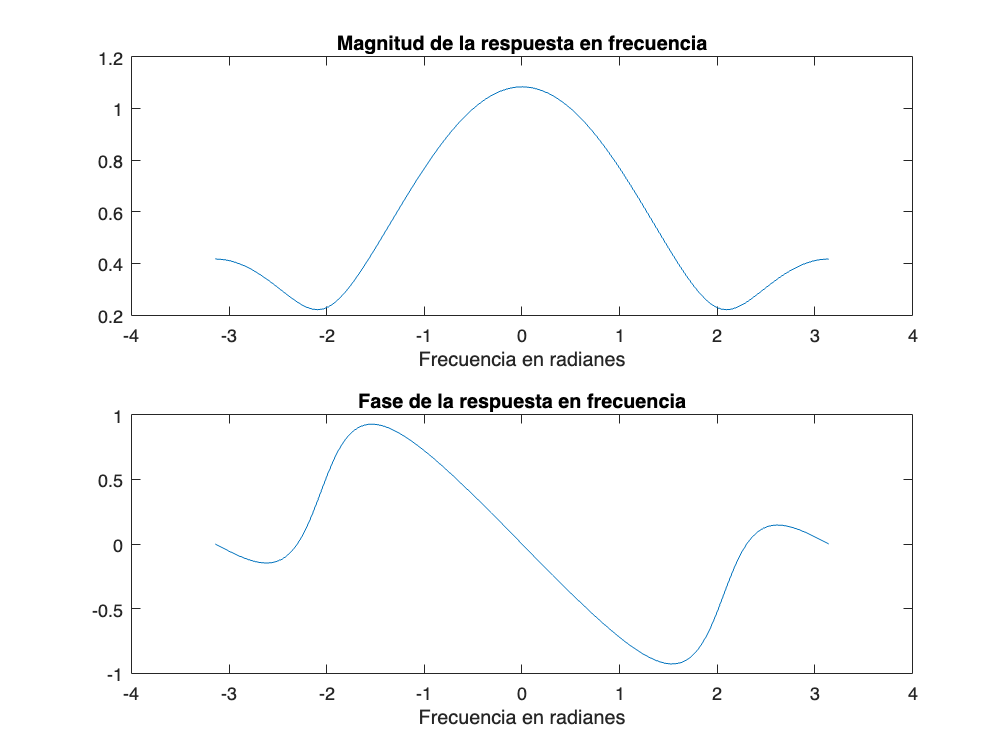

h=[1/2,1/3,1/4];
w=-pi:2*pi/120:pi;  % Así consigo 121 muestras
H=freqz(h,1,w);

figure;
subplot(211), plot(w,abs(H));
xlabel("Frecuencia en radianes");
title("Magnitud de la respuesta en frecuencia"),
subplot(212), plot(w,angle(H))
xlabel("Frecuencia en radianes");
title('Fase de la respuesta en frecuencia');

### **b) Representación de H(e^jw) y H(e^jpi/3)**

#### **Código**

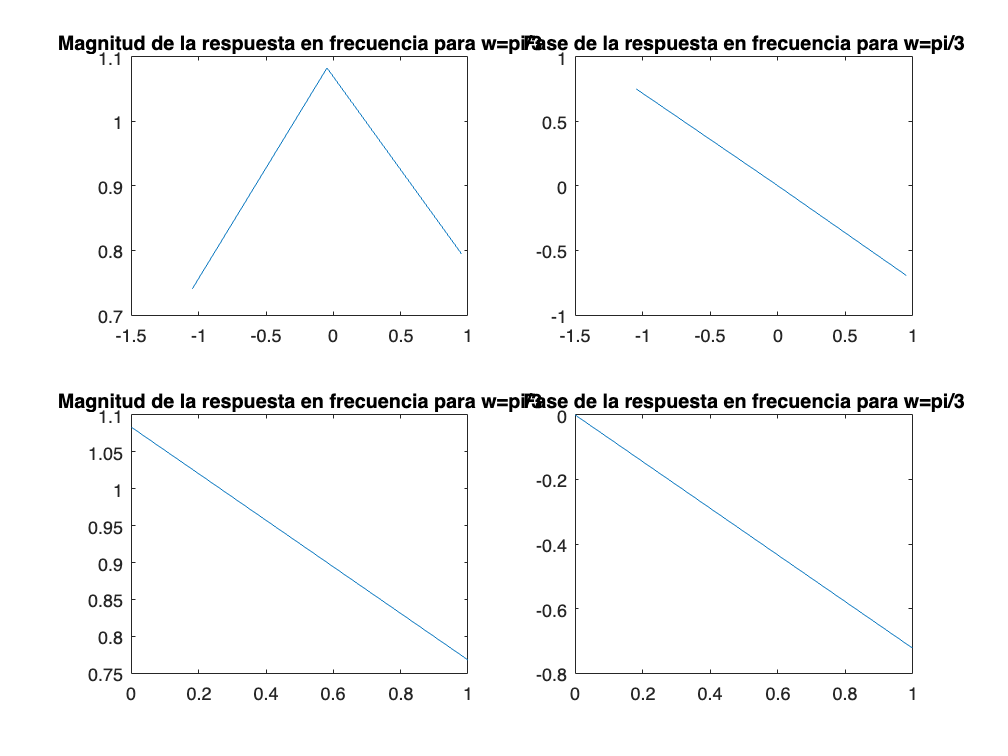

w = -pi/3:pi/3;
[H,w] = freqz(b,a,w);
w2 = 0:pi/3;
[H2,w2] = freqz(b,a,w2);

figure;
subplot(221), plot(w, abs(H)), title('Magnitud de la respuesta en frecuencia para w=pi/3');
subplot(222), plot(w, angle(H)), title('Fase de la respuesta en frecuencia para w=pi/3');
subplot(223), plot(w2, abs(H2)), title('Magnitud de la respuesta en frecuencia para w=pi/3');
subplot(224), plot(w2, angle(H2)), title('Fase de la respuesta en frecuencia para w=pi/3');

### d) ¿?

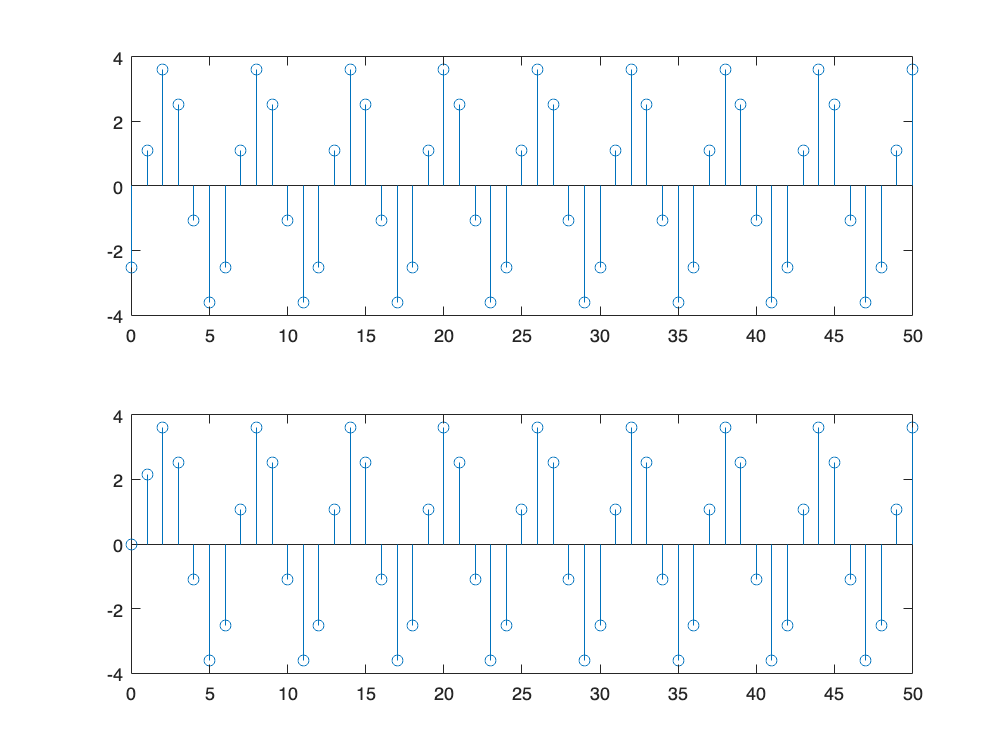

a=1;
n = 0:50;
h = [1/2 1/3 1/4];
x = 5*cos((pi/3).*n - pi/2);
w = [0 pi/3];
H = freqz(h, 1, w);
modulo_H = abs(H(2));
fase_H = angle(H(2));

y = 5 * modulo_H * cos((pi/3).*n - pi/2 + fase_H);

figure;
subplot (211)
stem (n,y)
y1= filter(h,1,x);
subplot(212);
stem (n,y1)

El inicio de la realizada a "mano" se reprenseta correctamente desde el inicio. Filter no, las dos primeras muestras no son correctas.

## 2.4 Diseño de un banco de filtros FIR paso-banda

Un filtro paso-namda elimina o atenúa todas las frecuencias que no se hayan en su banda de paso. Un modo simple de definir la respuesta al impulos de un filtro FIR paso-banda de L puntos es:


$$h\left\lbrack n\right\rbrack \;=\frac{2}{L}\cos \left(\frac{2\pi f_c }{f_s }n\right)\;\;\;\;\;\;\;\;0\le n\le L-1$$


### a) 

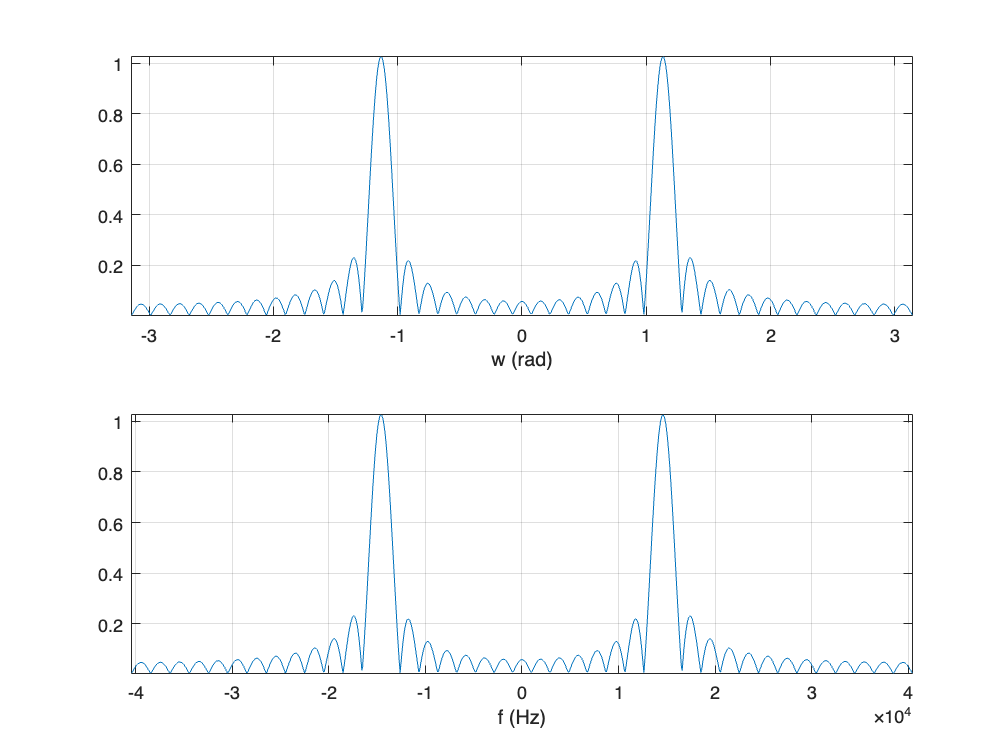

fs = 8192;
fc = 1477;
L = 40; %Valor arbitrario
n = 0:L-1;
w = -pi:(2*pi/1000):pi; % Cojo 1000 valores entre -pi y pi para la representación
h = 2/L*cos(((2*pi*fc)/(fs)).*n);
f = w*fs/2*pi;  % frecuencia en herzios;

H = freqz(h,1,w);   % w = radianes SIEMPRE

figure;
% El máximo se da en w = 1.14354 rad:
subplot(211), plot(w,abs(H))    % Representación en radianes
grid, axis tight, xlabel('w (rad)');

% El máximo se da en f = 14634.2 Hz:
subplot(212), plot(f,abs(H))    % Representación en Hercios
grid, axis tight, xlabel ('f (Hz)');

### b)

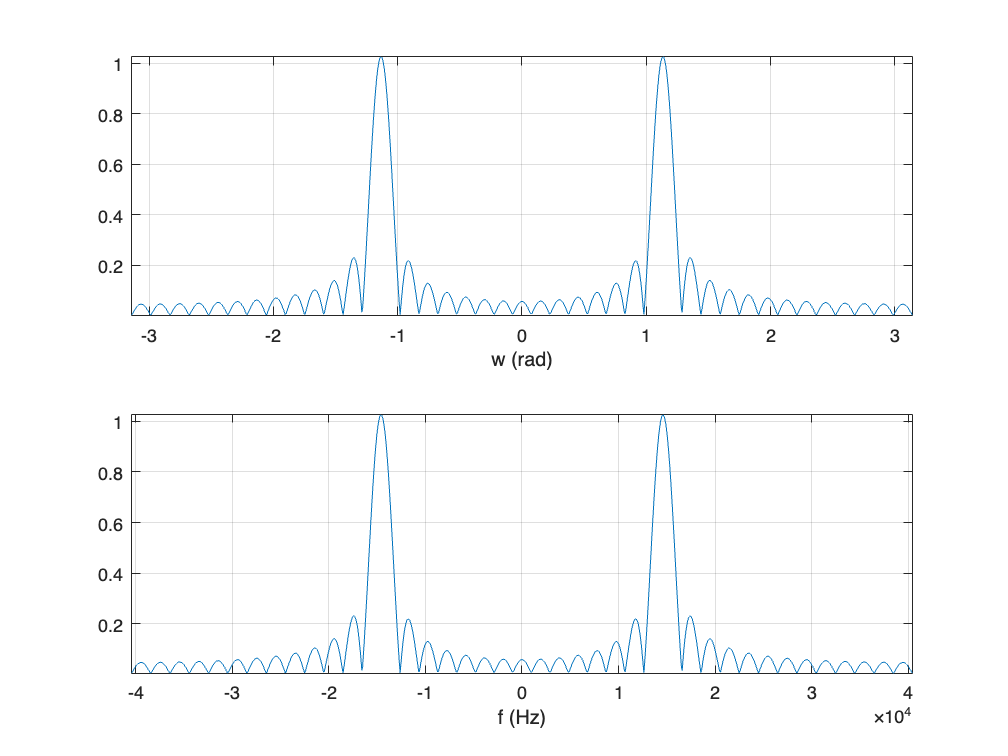

fc = 852;
H = freqz(h,1,w);

figure;
% El máximo se da en w = 0.659734 rad:
subplot(211), plot(w,abs(H))    % Representación en radianes
grid, axis tight, xlabel('w (rad)');

% El máximo se da en f = 8327.74 Hz:
subplot(212), plot(f,abs(H))    % Representación en Hercios
grid, axis tight, xlabel ('f (Hz)');

### d)

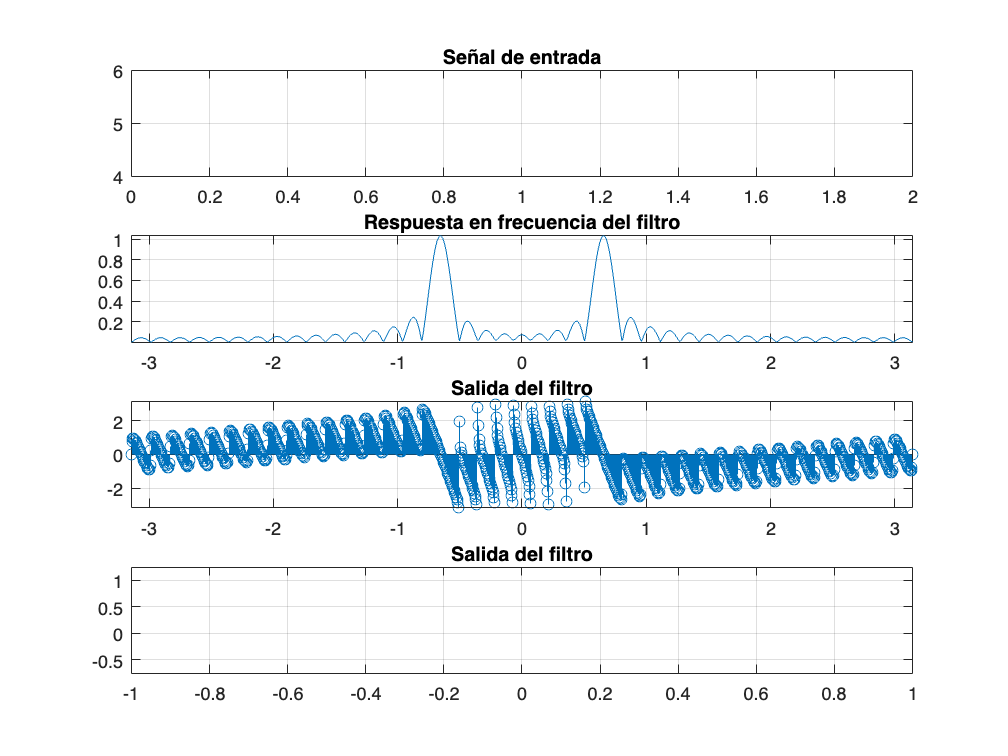

t = 0:fs:0.5; % de 0 a 0.5 de 0.01 en 0.01
x = 5*cos((2*pi*852)*t);
fs = 8192;
L = 40;

fc = 852; % Se saca de x
[y, h] = firpasobandaC(fs, fc, L, x);

### e)

Cuanto mas longitud da mejor selectivo

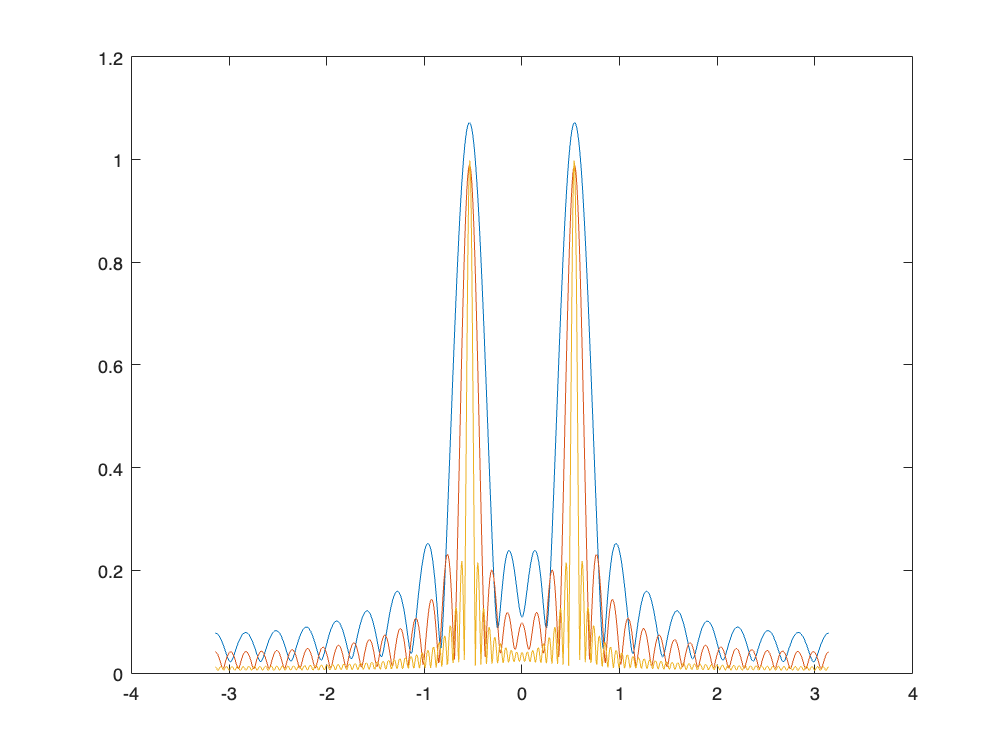

figure;
fs=8192;
fc=697;
Ls=[20,40,110];
w=-pi:(2*pi/1000):pi;
for l=1:length(Ls)
    n=0:Ls(l)-1;
    h1=(2/Ls(l))*cos(2*pi*fc*n/fs);
    H1=freqz(h1,1,w);
    plot(w,abs(H1));hold on
end

## 2.5 Utilización de un banco de filtros paso-banda para la decodicicación de una señalo DTMF

### a)

La longitud más adecuada es la mayor: L=110

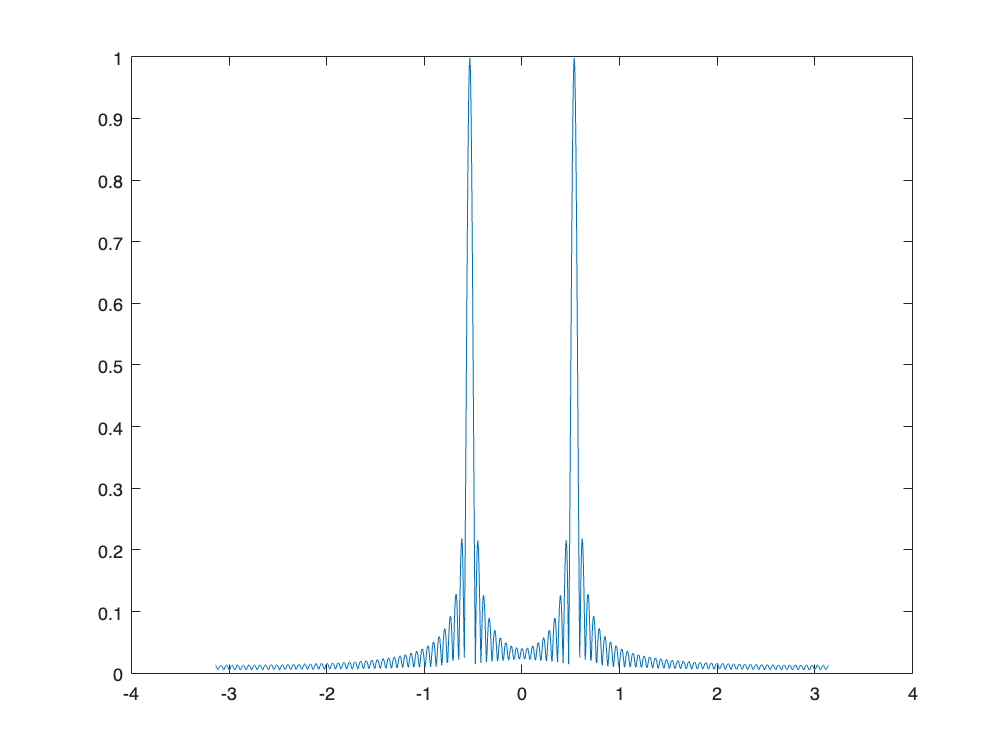

figure;
fs=8192;
fc=697;
Ls=110;
w=-pi:(2*pi/1000):pi;
n=0:Ls-1;
h=(2/Ls)*cos((2*pi*fc/fs).*n);
H = freqz(h,1,w);
modulo_H = abs(H);
plot(w,modulo_H)

### b)

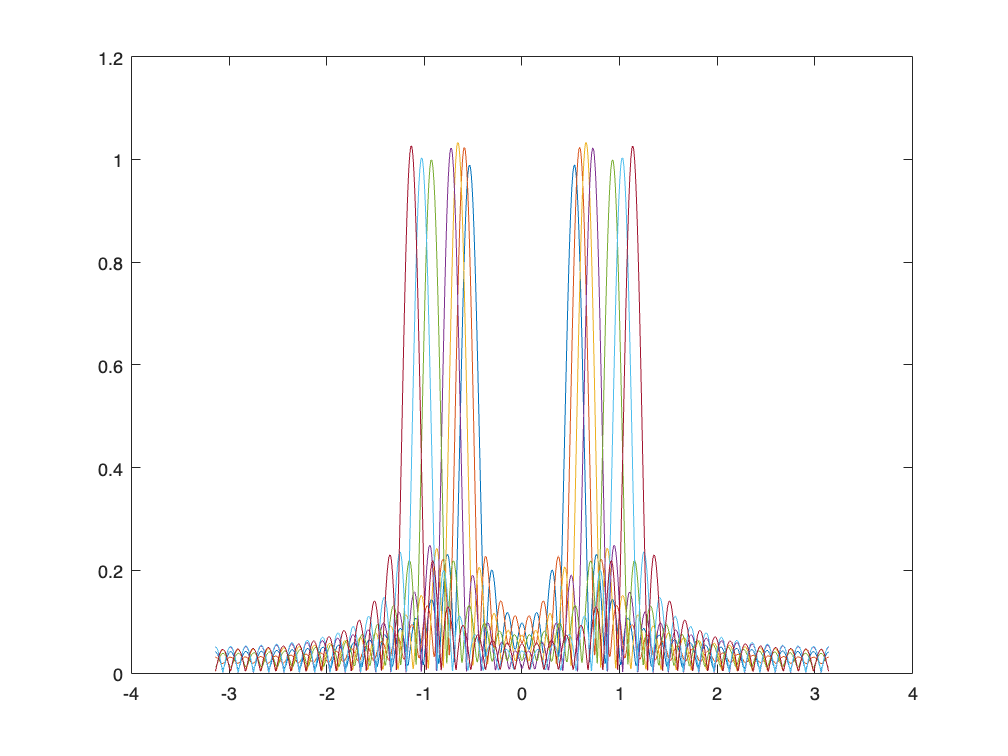

fc=[697,770,852,941,1209,1336,1477];
[h,H]=bancodefiltrosBP(fs,L,fc);

### c)

Lo cumple para la 4ª y la 6ª

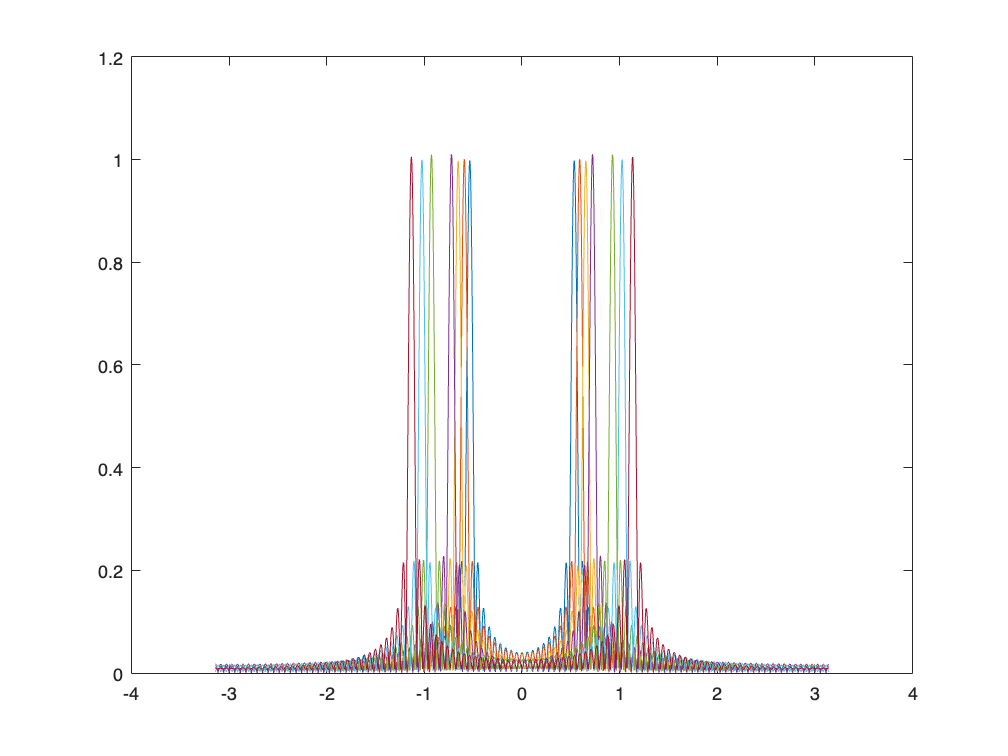

load digitoDTMF.mat;
L=110;
[h,H]=bancodefiltrosBP(fs,L,fc);

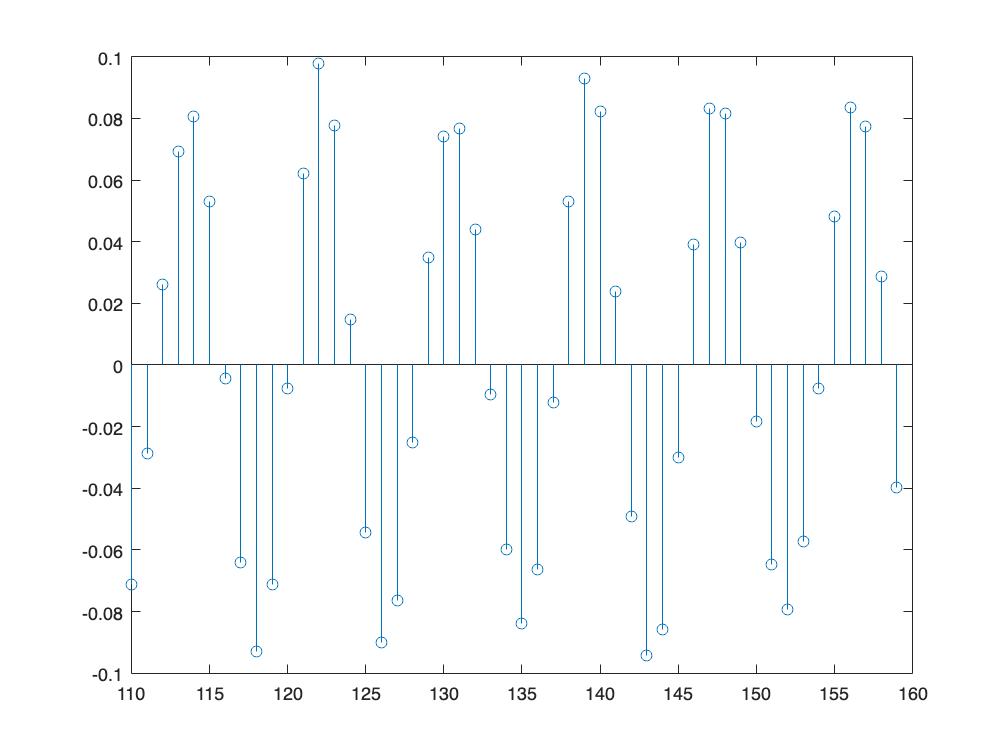

n=110:159;
for m=1 size(h,1);
    
    y=filter(h(m,:),1,digitoDTMF);
    figure;
    stem (n,y(n));

end

## e)

n=0:499;
x= cos(2*pi*941*n/fs)+cos(2*pi*1477*n/fs);

## 2.6 Filtro IIR de primer orden

La herramienta fvtool de Matlab permite el análisis de filtros digitales expresados mediante ecuación en diferencias.

Su llamada debe hacerse como: 				

     ** >> fvtool (b,a)	**

donde:

- b: vector con los coeficientes del numerador de H(z) 

- a: vector con los coeficientes del denominador de H(z) 					

'fvtool' permite, entre otras opciones, calcular y representar la respuesta en frecuencia del filtro en módulo y fase, el diagrama de polos y ceros, la respuesta al impulso. Todas estas opciones están accesibles en el menú Analysis o mediante los correspondientes iconos. Una vez seleccionado un tipo de análisis, los parámetros del mismo se pueden cambiar mediante la opción Analyis parameters del menú Analysis. Por ejemplo, es posible seleccionar si las gráficas de la magnitud de la respuesta en frecuencia van en dB o en unidades naturales o se puede fijar el rango de frecuencias de interés. En cada caso se tendrá que escoger las opciones más interesantes para el objetivo de análisis buscado. 	 

### a)

b=[1 0.81];
a=[1 -0.9];
fvtool(b,a)
%analysis>sampling frequency>fs=8000Hz
%analysis>analysis parameters>magnitude display>magnitude>frequency
%range>-fs/2,fs/2
%Lo volvemos a cambiar a dB, vemos que el máximo vale 25.15 en f=0kHz,
%buscamos donde cae 3dB, sería en 0.133kHz

## 2.7 Diseño de filtros IIR

Un “**notch filter**” (filtro de ranura o filtro de hendidura) es un filtro utilizado para eliminar una determinada frecuencia. El objetivo es conseguir diseñar un filtro de este tipo con una ranura muy estrecha para que las frecuencias colindantes se vean afectadas lo menos posible. Este filtro puede ser sintetizado mediante la conexión en cascada de un filtro FIR y un IIR. Para eliminar la frecuencia deseada basta con situar un par de ceros complejos conjugados en el círculo unidad con fase la frecuencia a eliminar resultando así un filtro FIR de ranura. El inconveniente de este filtro FIR es que tiene un ancho de ranura relativamente grande, lo que significa que no sólo elimina la frecuencia de interés, sino que también se atenúan otras componentes de frecuencias vecinas. Para controlar el ancho de banda de la ranura se sitúan polos con la misma fase que los ceros pero con una magnitud ligeramente inferior. El efecto de los polos es introducir resonancia en la vecindad de los ceros, y por lo tanto reducir el ancho de la ranura del “notch”. 		

Considera los filtros FIR e IIR de segundo orden cuyas magnitudes de las respectivas respuestas en frecuencia se representan en la siguiente figura. (El eje de frecuencias está normalizado por π ): 

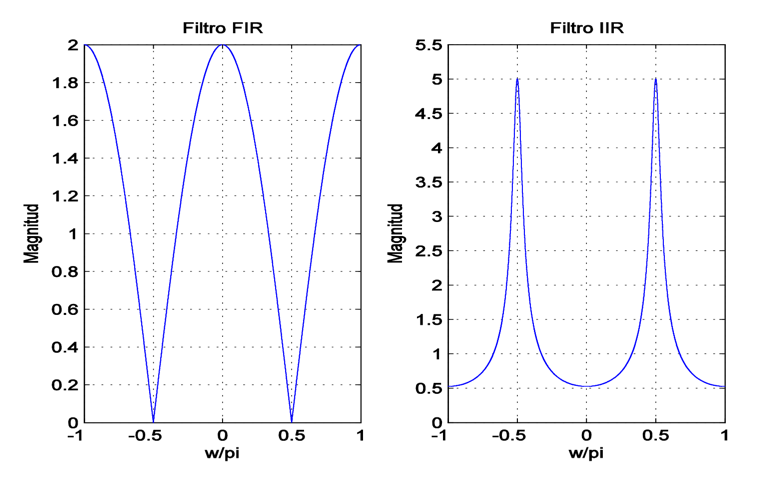

### a)

A la vista de las figuras la cascada del filtro notch eliminará muy selectivamente las frecuencias angulares **+-pi/2**.

### b)

**H(z)=1+z^(-2)**

### c)

%FIR
b1=[1 0 1];
a1=1;
fvtool(b1,a1)

%IIR
b2=0.95;
a2=[1 0 0.81];
fvtool(b2,a2)

### d - f)

%Ambos en cascada
b3=b1.*b2;
a3=a1.*a2;
fvtool(b3,a3)
%Cambiamos en las graficas la magnitud y el rango representado.

### e)

En las graficas anteriores, vamos a **anlaysis>pole/zero plot**

### **g)**

La sinusoide con frecuencia pi/2 no afecta a la gráfica

n=0:100;
x1=5*cos(n.*(pi/2));
x2=2*cos(n.*(pi/3));
x=x1+x2;
y=filter(b3,a3,x)

y =     6.6500    0.9500   -4.4365   -1.7195    1.6936    0.4428   -0.4218    1.5413    1.2916   -2.1985   -2.9462    0.8308    3.3365    1.2271   -1.7525   -1.9439   -0.4805    0.6246    1.3392    1.3941   -0.1347   -2.0792   -1.7909    0.7342    2.4006    1.3053   -0.9945   -2.0073   -1.0945    0.6759    1.8365    1.3525   -0.5376   -2.0455   -1.4646    0.7069    2.1363    1.3274   -0.7804   -2.0252   -1.2679    0.6904    1.9770    1.3408   -0.6514   -2.0360   -1.3724    0.6992    2.0616    1.3337


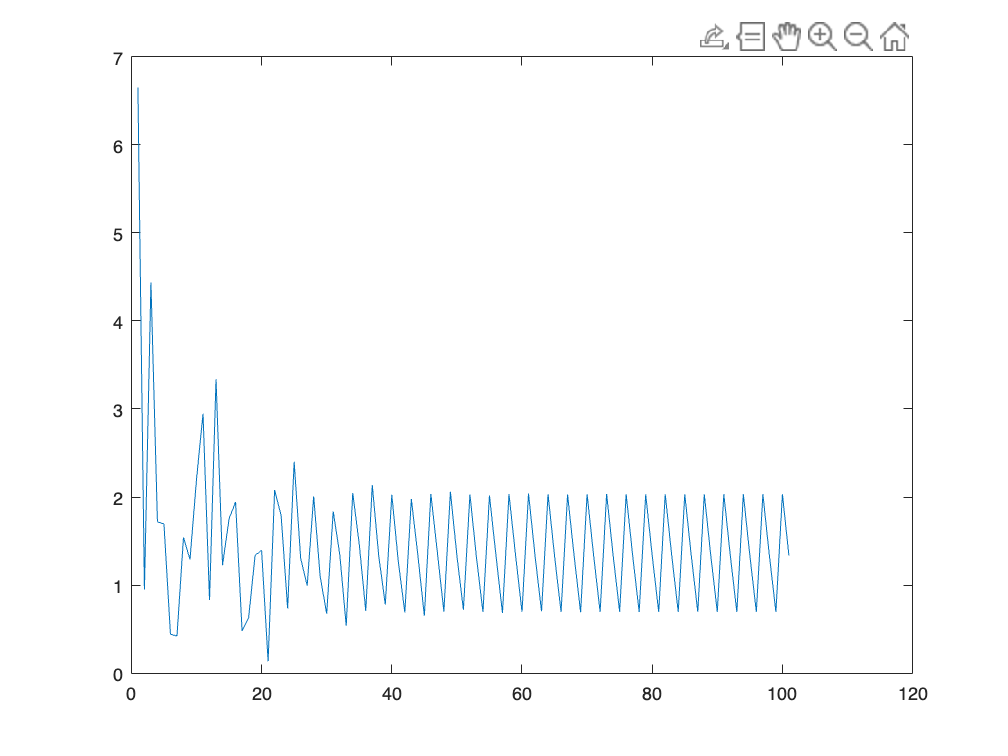

plot(abs(y))

## 2.8 Generación de un eco con un filtro FIR			

Es muy sencillo generar un eco en una señal mediante un filtro FIR de la forma: 

    
$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack$$
		

## a)

%alpha seria 0.9 (atenuacion del 10%) y D seria 4096, ya que 8192
%considera las muestras de un segundo completo, por tanto 4096
%considera la mitad (0.5s).
%y[n] = x[n] + alphax[n-D] => bk=[1, 0, ..., 0, 0.9] k=0 -> 1, k=D=0.9
fs = 8192;
D = fs/2     %considera la mitad (0.5s).

D = 4096

b1=[1 zeros(1,D-1) 0.9];
a1=1;
fvtool(b1,a1)

Invalid or deleted object.

Error in sigtools.sigfig/double (line 822)
      hFig = this.FigureHandle;

Error in fvtool (line 160)
refresh(double(hObj));

### b) ¿?

clear
fs = 8192;
D = fs/2;
b1=[1 zeros(1,D-1) 0.9];
a1=1;
load handel
filter(b1,a1,y)
sound(y,fs)

## 2.9) Desconvolución

El proceso de desconvolución consiste en recuperar la señal de entrada a un sistema haciendo pasar la salida por el sistema inverso. El cálculo del sistema inverso es sencillo trabajando en el dominio de la transformada Z. 				

En el apartado anterior se generaba un eco en una señal mediante un filtro FIR. El objetivo de este apartado es conseguir un filtro que elimine este eco.

### a) ¿?

a1=1;
b1=[1 zeros(1,4095) 0.9];   % D-1 = 4095
H = freqz(b1,a1,y)

H =    1.9000 + 0.0000i
   1.8967 + 0.0769i
   1.7773 - 0.4537i
   0.6223 + 0.8169i
   1.8967 - 0.0769i
   1.4544 + 0.7769i
   0.7669 - 0.8693i
   0.6935 + 0.8462i
   0.6223 + 0.8169i
   1.7773 - 0.4537i


### b)

a2=[1 zeros(1,4095) 0.9];
b2=1;
H = freqz(b2,a2,y)

H =    0.5263 + 0.0000i
   0.5264 - 0.0213i
   0.5282 + 0.1348i
   0.5901 - 0.7746i
   0.5264 + 0.0213i
   0.5349 - 0.2857i
   0.5707 + 0.6469i
   0.5794 - 0.7069i
   0.5901 - 0.7746i
   0.5282 + 0.1348i


### c)¿?

load handel
sound y

Error using sound
Audio data must be real and floating point.

filter(b1,a1,y)
sound y

load handel
filter(b2,a2,y)

## 2.3 Definición de una función en Matlab

c)

fs = 8192;
fc = 1447;
%h = (2/L)*cos(())
[H,w] = freqz(b,a,n)

H =       13/12     +    0i          1367/2373   - 1787/3519i      335/1693   -  395/3468i      547/1334   +  473/20733i     332/1351   +   53/10755i     693/1801   + 1166/2559i     1263/1225   + 1148/5051i      736/937    - 1609/3448i      179/844    -  883/3425i      739/2045   +  330/6551i      166/515    -  105/2239i      127/505    +  405/1207i     2276/2565   +  787/1942i     1401/1453   -  585/1769i      526/1725   -  269/676i       107/375    +  127/4199i      387/994    -  322/7687i      731/3727   +  220/1169i      770/1119   +  433/869i       469/439    -  523/4216i      405/863    -  339/691i       262/1205   -  345/6934i     1332/3197   -   55/37287i     260/1213   +  567/10013i    1717/3567   +  447/905i       359/335    +  148/1349i      629/932    -  297/593i       390/1997   -  269/1502i      633/1613   +  355/8856i     3701/13197  -  181/6702i      433/1382   + 1243/3065i      911/936    + 1629/5099i     1265/1444   -  641/1549i      354/1441   - 4328/13249i     443/1

w =        0              1              2              3              4              5              6              7              8              9             10             11             12             13             14             15             16             17             18             19             20             21             22             23             24             25             26             27             28             29             30             31             32             33             34             35             36             37             38             39             40             41             42             43             44             45             46             47             48             49             50             51             52             53             54             55             56             57             58             59             60             61             62             63             64             65             

## firpasobanda.m

function [h, y] = firpasobandaC (fs, fc, L, x)    %Declaración de la función (Aquí van los parametros de entrada de la función)
% Parametros de entrada: (fs, fc, L, x)     || Parametros de salida: (h, y)
% FIRPASOBANDA Summary of this function goes here
%       Detailed explanation goes here
%       Programación de la función
n = 0:L-1;
w = -pi:(2*pi/1000):pi; % 1000 valores entre -pi y pi
h = (2/L) * cos(((2*pi*fc)/fs).*n);

H = freqz(h,1,w);   % Tiene que estar siempre en radianes

%SALIDAS:
h = (2/L) * cos(((2*pi*fc)/fs).*n);
y = filter(h,1,x); %Filtro paso-banda generado (respuesta al impulso)

figure 
H = freqz(h,1,w);   % Tiene que estar siempre en radianes

subplot(411), plot(x)
grid, axis tight, title ('Señal de entrada');

subplot(412), plot(w,abs(H))
grid, axis tight, title ('Respuesta en frecuencia del filtro');

subplot(413), stem (w, angle(H))
grid, axis tight, title ('Salida del filtro');

subplot(414), plot((0: length(y)-1),y)
grid, axis tight, title ('Salida del filtro');
end